# EGH445 Modern Control - Introduction

Control is...

## Introduction

Quick unit overview

### Motivation

Classic Control vs Modern Control. What can you do with Modern Control that you couldn't before?

% Example 1
A = [-1    0;
     1    0];
eig(A)

ans =      0
    -1


B = [ 1 ;
      0  ];
C = [ 1  0];
D = [ 0 ];
[TFnum, TFden] = ss2tf(A,B,C,D);
TF = tf(TFnum, TFden);
minreal(TF) % pole-zero cancelation


ans =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


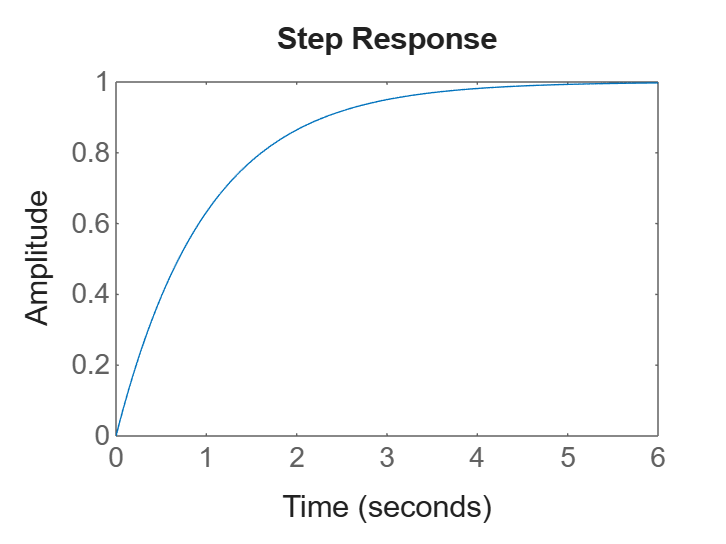

step(TF)

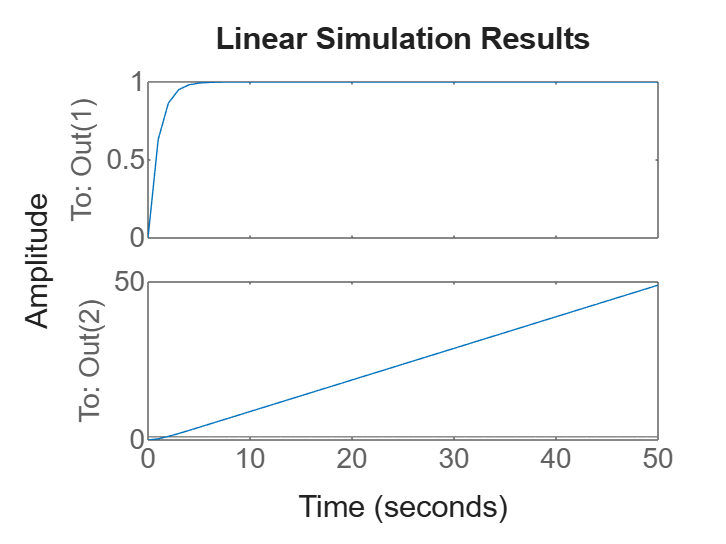

tspan = 0:1:50;
u = ones(length(tspan),1);
lsim(ss(A,B,eye(2),D), u, tspan)

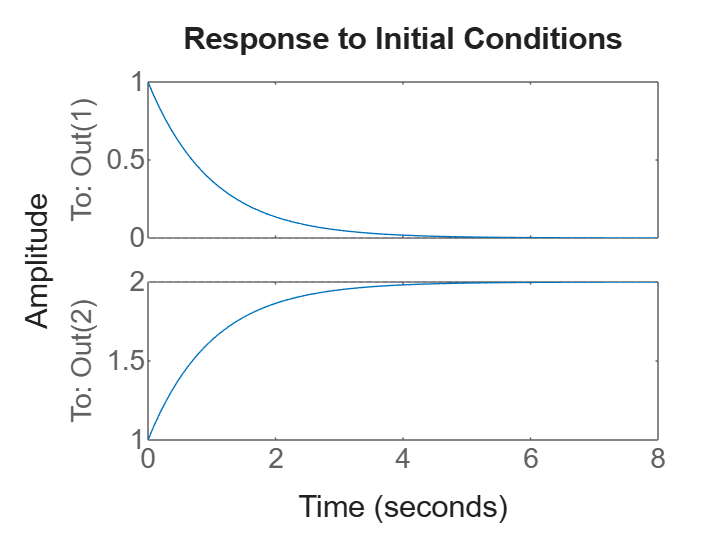

initial(ss(A,B,eye(2),D), [1 1])

## Dynamic Systems

### Examples

One example of each domain (electrical, mechanical, financial, biological) 

### Ordinary Differential Equations (ODEs)

### Block Diagrams

### Transfer Functions

### State-space Models

## Model Conversions

## ODE to Transfer Functions (and vice-versa)

## ODE to State-Space Equations

## Transfer Functions to State-Space Equations (and vice-versa)

This is the live script of Week 1's Lecture

x = 1

x = 1

As you can see, `x = 1`.